clear

AR = 8.5;
Sweep = 0;
Taper = 0.531;
c_bar = 3.58;
srefref = 101.925;
fuselage_rad = 1.25;
twist = -3;
panelnum = 5;
Uinf = 1;

incidence = 1;


airfoil(1).Field = 'root';
airfoil(1).alpha0 = -3;
airfoil(1).a = 1;
airfoil(2).Field = 'tip';
airfoil(2).alpha0 = -3;
airfoil(2).a = 1;


%% discritize planform to plot
[Sref, c_y, span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)

Sref = 102.5302

c_y =     4.5370    4.5356    4.5341    4.5327    4.5313    4.5298    4.5284    4.5269    4.5255    4.5241    4.5226    4.5212    4.5197    4.5183    4.5168    4.5154    4.5140    4.5125    4.5111    4.5096    4.5082    4.5068    4.5053    4.5039    4.5024    4.5010    4.4995    4.4981    4.4967    4.4952    4.4938    4.4923    4.4909    4.4895    4.4880    4.4866    4.4851    4.4837    4.4822    4.4808    4.4794    4.4779    4.4765    4.4750    4.4736    4.4722    4.4707    4.4693    4.4678    4.4664


span_disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


MACpos = 665


semispan = length(span_disc)*0.01

semispan = 14.7700


thetadist = acos(span_disc/span_disc(end))

thetadist =     1.5708    1.5701    1.5694    1.5688    1.5681    1.5674    1.5667    1.5661    1.5654    1.5647    1.5640    1.5633    1.5627    1.5620    1.5613    1.5606    1.5600    1.5593    1.5586    1.5579    1.5572    1.5566    1.5559    1.5552    1.5545    1.5539    1.5532    1.5525    1.5518    1.5511    1.5505    1.5498    1.5491    1.5484    1.5478    1.5471    1.5464    1.5457    1.5450    1.5444    1.5437    1.5430    1.5423    1.5417    1.5410    1.5403    1.5396    1.5389    1.5383    1.5376



twist_dis = linspace(twist,0,length(span_disc))

twist_dis =    -3.0000   -2.9980   -2.9959   -2.9939   -2.9919   -2.9898   -2.9878   -2.9858   -2.9837   -2.9817   -2.9797   -2.9776   -2.9756   -2.9736   -2.9715   -2.9695   -2.9675   -2.9654   -2.9634   -2.9614   -2.9593   -2.9573   -2.9553   -2.9533   -2.9512   -2.9492   -2.9472   -2.9451   -2.9431   -2.9411   -2.9390   -2.9370   -2.9350   -2.9329   -2.9309   -2.9289   -2.9268   -2.9248   -2.9228   -2.9207   -2.9187   -2.9167   -2.9146   -2.9126   -2.9106   -2.9085   -2.9065   -2.9045   -2.9024   -2.9004


alpha_0_dis = linspace(airfoil(1).alpha0,airfoil(2).alpha0,length(span_disc))

alpha_0_dis =     -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


incidence_dis = incidence*ones(1,length(span_disc))

incidence_dis =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


alpha_dis = twist_dis - alpha_0_dis + incidence_dis

alpha_dis =     1.0000    1.0020    1.0041    1.0061    1.0081    1.0102    1.0122    1.0142    1.0163    1.0183    1.0203    1.0224    1.0244    1.0264    1.0285    1.0305    1.0325    1.0346    1.0366    1.0386    1.0407    1.0427    1.0447    1.0467    1.0488    1.0508    1.0528    1.0549    1.0569    1.0589    1.0610    1.0630    1.0650    1.0671    1.0691    1.0711    1.0732    1.0752    1.0772    1.0793    1.0813    1.0833    1.0854    1.0874    1.0894    1.0915    1.0935    1.0955    1.0976    1.0996



a_dis = linspace(airfoil(1).a,airfoil(2).a,length(span_disc))

a_dis =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



mu_dis = (a_dis.*c_y)/(8.*semispan)

mu_dis =     0.0384    0.0384    0.0384    0.0384    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0383    0.0382    0.0382    0.0382    0.0382    0.0382    0.0382    0.0382    0.0382    0.0381    0.0381    0.0381    0.0381    0.0381    0.0381    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380    0.0380    0.0380    0.0380    0.0379    0.0379    0.0379    0.0379    0.0379    0.0379    0.0379    0.0379    0.0378    0.0378    0.0378    0.0378    0.0378



LHS = zeros(panelnum,1);
RHS = zeros(panelnum,panelnum);

for i = 1:panelnum
    for j = 1 : panelnum
        tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)))
        LHS(i,1) = mu_dis(tempind)*alpha_dis(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end

tempind = 147

tempind = 147

tempind = 147

tempind = 147

tempind = 147

tempind = 443

tempind = 443

tempind = 443

tempind = 443

tempind = 443

tempind = 738

tempind = 738

tempind = 738

tempind = 738

tempind = 738

tempind = 1033

tempind = 1033

tempind = 1033

tempind = 1033

tempind = 1033

tempind = 1329

tempind = 1329

tempind = 1329

tempind = 1329

tempind = 1329

Aseries = RHS\LHS

Aseries =     0.0825
    0.0344
    0.0032
    0.0027
   -0.0021


gamma_span_coef = 4*semispan*Uinf

gamma_span_coef = 59.0800

gamma_sum = 0

gamma_sum = 0


for n = 1:panelnum
    gamma_sum = gamma_sum + Aseries(n)*sin(n*thetadist)
end

gamma_sum =     0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0825    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824    0.0824


gamma_sum =     0.0825    0.0825    0.0826    0.0826    0.0826    0.0827    0.0827    0.0828    0.0828    0.0829    0.0829    0.0830    0.0830    0.0831    0.0831    0.0832    0.0832    0.0832    0.0833    0.0833    0.0834    0.0834    0.0835    0.0835    0.0836    0.0836    0.0837    0.0837    0.0838    0.0838    0.0838    0.0839    0.0839    0.0840    0.0840    0.0841    0.0841    0.0842    0.0842    0.0842    0.0843    0.0843    0.0844    0.0844    0.0845    0.0845    0.0846    0.0846    0.0847    0.0847


gamma_sum =     0.0792    0.0793    0.0793    0.0794    0.0794    0.0795    0.0795    0.0796    0.0796    0.0796    0.0797    0.0797    0.0798    0.0798    0.0799    0.0799    0.0800    0.0800    0.0801    0.0801    0.0802    0.0802    0.0802    0.0803    0.0803    0.0804    0.0804    0.0805    0.0805    0.0806    0.0806    0.0807    0.0807    0.0808    0.0808    0.0808    0.0809    0.0809    0.0810    0.0810    0.0811    0.0811    0.0812    0.0812    0.0813    0.0813    0.0813    0.0814    0.0814    0.0815


gamma_sum =     0.0792    0.0793    0.0793    0.0793    0.0794    0.0794    0.0795    0.0795    0.0795    0.0796    0.0796    0.0797    0.0797    0.0797    0.0798    0.0798    0.0799    0.0799    0.0799    0.0800    0.0800    0.0800    0.0801    0.0801    0.0802    0.0802    0.0802    0.0803    0.0803    0.0804    0.0804    0.0804    0.0805    0.0805    0.0806    0.0806    0.0806    0.0807    0.0807    0.0807    0.0808    0.0808    0.0809    0.0809    0.0809    0.0810    0.0810    0.0810    0.0811    0.0811


gamma_sum =     0.0771    0.0772    0.0772    0.0772    0.0773    0.0773    0.0774    0.0774    0.0774    0.0775    0.0775    0.0776    0.0776    0.0776    0.0777    0.0777    0.0777    0.0778    0.0778    0.0779    0.0779    0.0779    0.0780    0.0780    0.0781    0.0781    0.0781    0.0782    0.0782    0.0783    0.0783    0.0783    0.0784    0.0784    0.0785    0.0785    0.0785    0.0786    0.0786    0.0787    0.0787    0.0787    0.0788    0.0788    0.0788    0.0789    0.0789    0.0790    0.0790    0.0790



gamma_plot = gamma_span_coef*gamma_sum

gamma_plot =     4.5562    4.5585    4.5609    4.5632    4.5655    4.5678    4.5701    4.5725    4.5748    4.5771    4.5794    4.5817    4.5841    4.5864    4.5887    4.5910    4.5934    4.5957    4.5980    4.6003    4.6026    4.6050    4.6073    4.6096    4.6119    4.6143    4.6166    4.6189    4.6212    4.6235    4.6259    4.6282    4.6305    4.6328    4.6351    4.6375    4.6398    4.6421    4.6444    4.6468    4.6491    4.6514    4.6537    4.6560    4.6584    4.6607    4.6630    4.6653    4.6676    4.6700


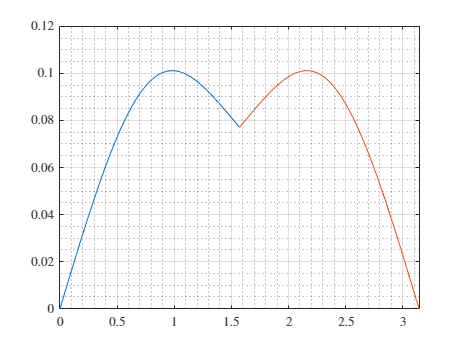

plot(thetadist,gamma_sum)
hold on
plot(-thetadist+pi,gamma_sum)
grid on
grid minor
xlim([0 pi])

function [Sref, c_y,span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)
s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
Sref_1 = (1 + Taper) * s_1;
span_disc_1 = [0:0.01:s_1];
c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
s = ratio*s_1;
Sref = ratio * (1 + Taper) * s;
span_disc = [0:0.01:s];
c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
temp1 = (c_y - c_bar).^2;
MACpos = find(temp1 == min(temp1));
quarterchord =  span_disc .* tand(Sweep);
end